# FABRIC DEFECT DETECTION

# TILDA DATASET - COMPARECLASSIFIERS_MULTI

Compare the performance of the classifiers for the multiclass classification FABRIC DEFECT DETECTION. 

## Prepare data

DATA = xlsread('IMPROVED_FABRICDATASET.xlsx');
num=array2table(DATA);


output=xlsread('data23.xlsx');
data23=array2table(output);
N = normalize(num);
N(:,23) = data23;
num1 = N(randperm(size(N, 1)), :);
save FABRICDATA.mat num1
load FABRICDATA

Divide the data into training and validation sets

rng(1234)
part = cvpartition(num1.Var23,'Holdout',0.2);
tridx = training(part);
tdata = num1(tridx,:);
vdata = num1(~tridx,:);
tdataAll = num1(tridx,:);
vdataAll = num1(~tridx,:);

**Create a table to hold the results**

mdlnames = {'kNN','kNN k=5','Weighted kNN k=5','Tree','Pruned tree',...
    'Tree (all predictors)','Pruned tree (all predictors)',...
    'NB','NB kernel','NB (all predictors)','NB kernel (all predictors)',...
    'Linear DA','Quadratic DA','Linear SVM','Gaussian SVM',...
    'Linear SVM (all predictors)','Gaussian SVM (all predictors)',...
    'Ensembles','Generalized Additive Model','Neural Network',...
    'Semi-supervised graph','Automated Model','Linear Classifier','Kernal Classifier'};
results = table(zeros(24,1),zeros(24,1),...
    'RowNames',mdlnames,'VariableNames',{'ResubLoss','Loss'});


## Confusion Matrix Parameters

#                                         TP    cm(1)  |   FP cm(3)

#                                         ---------------------------------

#                                          FN  cm(2)   |  TN cm(4)

**Formula for Confusion Matrix Parameters** 

SE = cm(1)/(cm(1)+cm(2))

SP = cm(4)/(cm(4)+cm(3))

AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

FAR=cm(3)/(cm(3)+cm(2))

DR=cm(4)/(cm(4)+cm(1))

PPV=cm(1)/(cm(1)+cm(3))


 mdlnames1 = {'kNN','kNN k=5','Weighted kNN k=5','Tree','Pruned tree',...
    'Tree (all predictors)','Pruned tree (all predictors)',...
    'NB','NB kernel','NB (all predictors)','NB kernel (all predictors)',...
    'Linear DA','Quadratic DA','Linear SVM','Gaussian SVM',...
    'Linear SVM (all predictors)','Gaussian SVM (all predictors)',...
    'Ensembles','Generalized Additive Model','Neural Network',...
    'Semi-supervised graph','Automated Model','Linear Classifier','Kernal Classifier'};
 Conf=table(zeros(24,1),zeros(24,1),zeros(24,1),zeros(24,1),...
     zeros(24,1),zeros(24,1),'RowNames',mdlnames1,'VariableNames',{'Sensitivity',...
     'Specificity','Detection accuracy','False alarm rate','Detection rate ',...
     'Positive predictive value (PPV) or Precision'});

## kNN models

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |       0.125 |     0.22526 |       0.125 |       0.125 |         1224 |  correlation |
|    2 | Accept |     0.12578 |    0.060578 |       0.125 |     0.12514 |            4 |      hamming |
|    3 | Accept |       0.125 |    0.081811 |       0.125 |     0.12511 |          147 |  mahalanobis |
|    4 | Best   |     0.10391 |    0.060463 |     0.10391 |     0.10748 |           44 |    chebychev |
|    5 | Accept |     0.10391 |    0.060788 |     0.10391 |     0.10391 |           44 |    chebychev |
|    6 | Best   |    0.098828 |    0.060137 |    0.098828 |    0

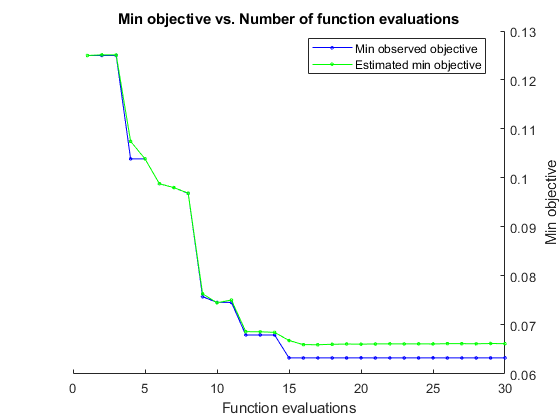

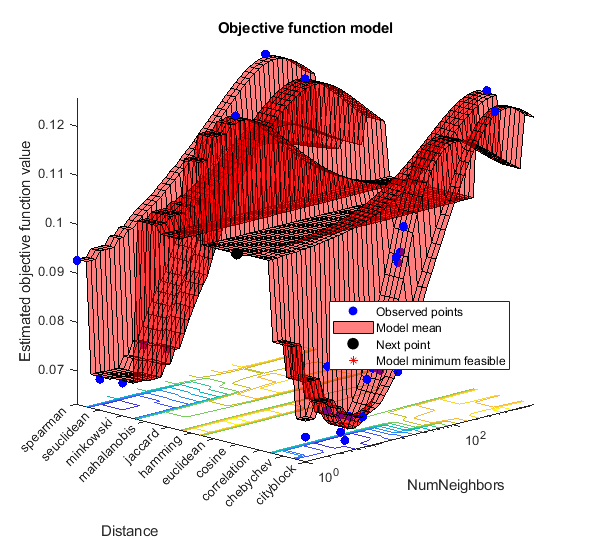


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 24.4746 seconds
Total objective function evaluation time: 2.2363

Best observed feasible point:
    NumNeighbors    Distance 
    ____________    _________

         7          chebychev

Observed objective function value = 0.063281
Estimated objective function value = 0.066202
Function evaluation time = 0.052838

Best estimated feasible point (according to models):
    NumNeighbors    Distance 
    ____________    _________

         7          chebychev

Estimated objective function value = 0.066202
Estimated function evaluation time = 0.05512



m =   ClassificationKNN
                       PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
                         ResponseName: 'Var23'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 2560
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                             Distance: 'chebychev'
                         NumNeighbors: 7


  Properties, Methods


m = fitcknn(tdata,'Var23','OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

results{1,:} = [resubLoss(m) loss(m,vdata)];

[HDpred,score]=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =     63    17
    28   532


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =        92.969


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |    0.071484 |    0.061002 |    0.071484 |    0.071484 |            3 |   seuclidean |
|    2 | Accept |       0.125 |     0.29409 |    0.071484 |    0.075233 |          958 |     spearman |
|    3 | Best   |    0.070703 |    0.050946 |    0.070703 |    0.072503 |            1 |    euclidean |
|    4 | Accept |       0.125 |     0.12384 |    0.070703 |    0.072776 |          505 |    cityblock |
|    5 | Accept |    0.082812 |    0.056219 |    0.070703 |    0.070744 |            2 |   seuclidean |
|    6 | Best   |    0.066016 |    0.061034 |    0.066016 |    0

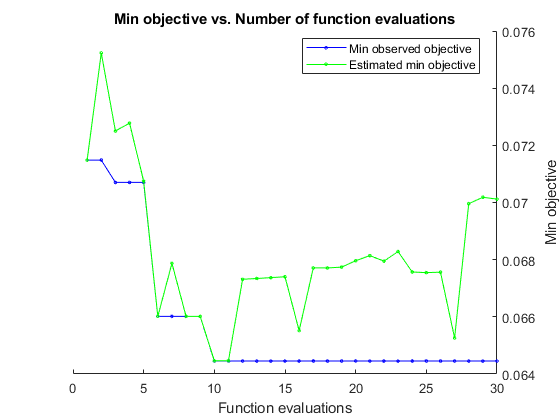

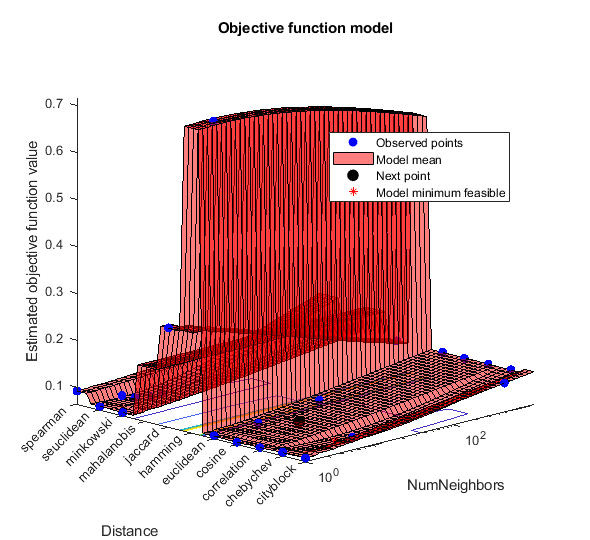


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 25.6112 seconds
Total objective function evaluation time: 2.9722

Best observed feasible point:
    NumNeighbors     Distance 
    ____________    __________

         5          seuclidean

Observed objective function value = 0.064453
Estimated objective function value = 0.072028
Function evaluation time = 0.062546

Best estimated feasible point (according to models):
    NumNeighbors     Distance 
    ____________    __________

         2          seuclidean

Estimated objective function value = 0.070119
Estimated function evaluation time = 0.056742



m =   ClassificationKNN
                       PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
                         ResponseName: 'Var23'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 2560
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                             Distance: 'seuclidean'
                         NumNeighbors: 2


  Properties, Methods


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(1,:)={SE,SP,AC,FAR,DR,PPV};

m.NumNeighbors = 5;
m = fitcknn(tdata,'Var23','OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

results{2,:} = [resubLoss(m) loss(m,vdata)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =     67    13
    41   519


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =        91.562


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |         0.1 |     0.16584 |         0.1 |         0.1 |            2 |     spearman |
|    2 | Accept |       0.125 |     0.12957 |         0.1 |     0.10099 |          550 |    chebychev |
|    3 | Accept |       0.125 |     0.18661 |         0.1 |     0.10102 |         1247 |      jaccard |
|    4 | Best   |    0.077734 |    0.053814 |    0.077734 |    0.079329 |           18 |    euclidean |
|    5 | Accept |       0.125 |    0.074354 |    0.077734 |    0.082032 |          106 |    euclidean |
|    6 | Accept |    0.077734 |    0.055803 |    0.077734 |    0

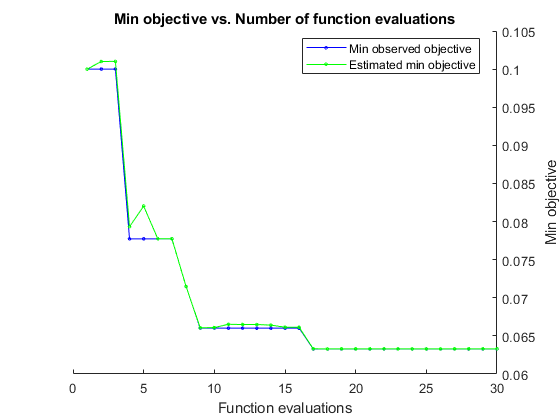

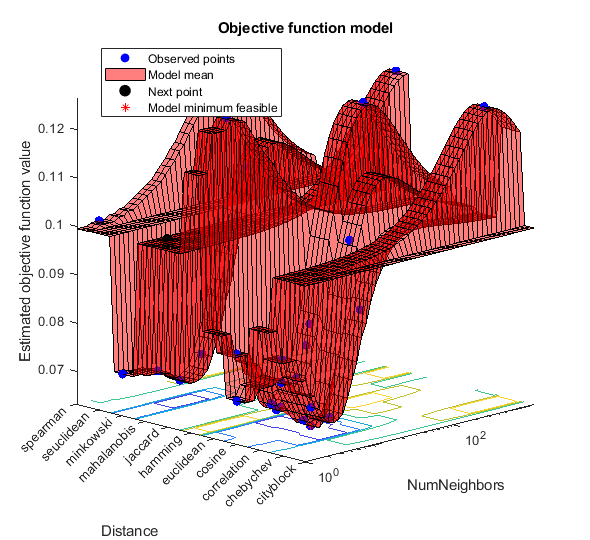


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 23.5831 seconds
Total objective function evaluation time: 2.1265

Best observed feasible point:
    NumNeighbors    Distance
    ____________    ________

         10          cosine 

Observed objective function value = 0.063281
Estimated objective function value = 0.063298
Function evaluation time = 0.053528

Best estimated feasible point (according to models):
    NumNeighbors    Distance
    ____________    ________

         10          cosine 

Estimated objective function value = 0.063298
Estimated function evaluation time = 0.05707



m =   ClassificationKNN
                       PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
                         ResponseName: 'Var23'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 2560
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                             Distance: 'cosine'
                         NumNeighbors: 10


  Properties, Methods


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(2,:)={SE,SP,AC,FAR,DR,PPV};

m.DistanceWeight = 'squaredinverse';
m = fitcknn(tdata,'Var23','OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

results{3,:} = [resubLoss(m) loss(m,vdata)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =     66    14
    26   534


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =         93.75


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(3,:)={SE,SP,AC,FAR,DR,PPV};

## Tree models

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |    0.098437 |    0.062632 |    0.098437 |    0.098437 |           30 |
|    2 | Accept |       0.125 |    0.036436 |    0.098437 |     0.10012 |         1145 |
|    3 | Accept |       0.125 |     0.04364 |    0.098437 |     0.09844 |          294 |
|    4 | Best   |     0.08125 |    0.062925 |     0.08125 |    0.081253 |            5 |
|    5 | Accept |    0.082422 |    0.061779 |     0.08125 |    0.081256 |            1 |
|    6 | Accept |    0.082422 |    0.061085 |     0.08125 |    0.081544 |            3 |
|    7 | Accept |    0.082422 |    0.061219 |     0.08125 |    0.081284 |            3 |
|    8 | Best   |    

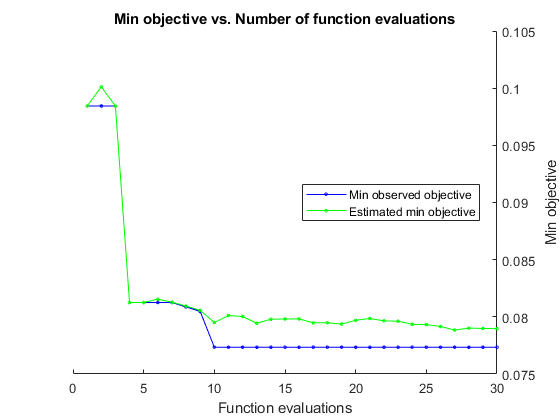

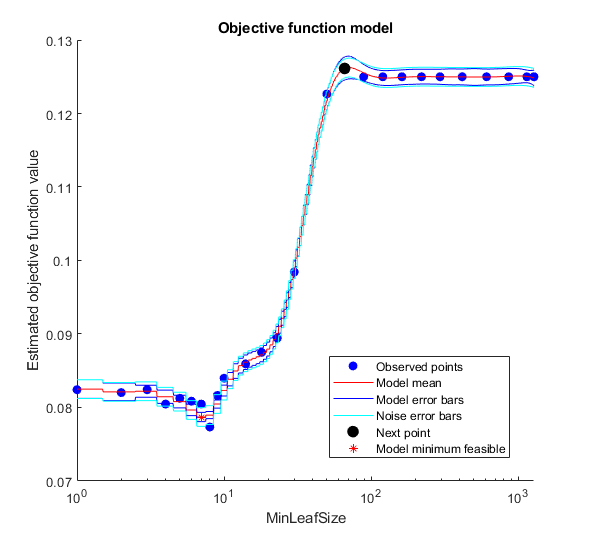


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 20.8263 seconds
Total objective function evaluation time: 1.6464

Best observed feasible point:
    MinLeafSize
    ___________

         8     

Observed objective function value = 0.077344
Estimated objective function value = 0.07897
Function evaluation time = 0.066543

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

         8     

Estimated objective function value = 0.07897
Estimated function evaluation time = 0.061879



m =   ClassificationTree
                       PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
                         ResponseName: 'Var23'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 2560
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


m = fitctree(tdata,'Var23','OptimizeHyperparameters','auto')

results{4,:} = [resubLoss(m) loss(m,vdata)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =     54    26
    28   532


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =        91.562


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(4,:)={SE,SP,AC,FAR,DR,PPV};

m = prune(m,'Level',4)

m =   ClassificationTree
                       PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
                         ResponseName: 'Var23'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 2560
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


results{5,:} = [resubLoss(m) loss(m,vdata)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =     51    29
    20   540


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =        92.344


|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |    0.085547 |     0.06135 |    0.085547 |    0.085547 |           14 |
|    2 | Accept |       0.125 |    0.043394 |    0.085547 |    0.087938 |          726 |
|    3 | Accept |    0.086328 |    0.062835 |    0.085547 |    0.085549 |            1 |
|    4 | Accept |       0.125 |    0.044325 |    0.085547 |    0.085551 |          182 |
|    5 | Best   |    0.083594 |    0.060721 |    0.083594 |     0.08359 |            4 |
|    6 | Accept |    0.084375 |    0.058946 |    0.083594 |    0.083608 |            7 |
|    7 | Accept |    0.087891 |    0.060516 |    0.083594 |    0.083705 |            2 |
|    8 | Accept |    

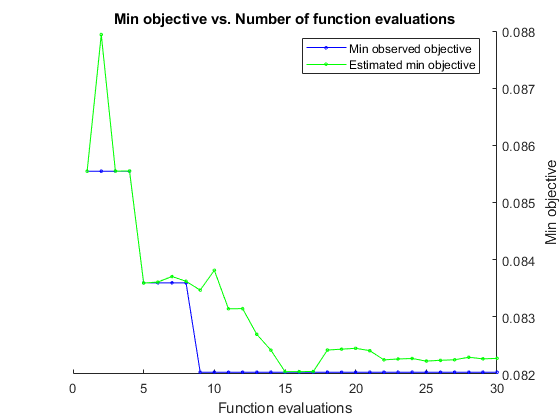

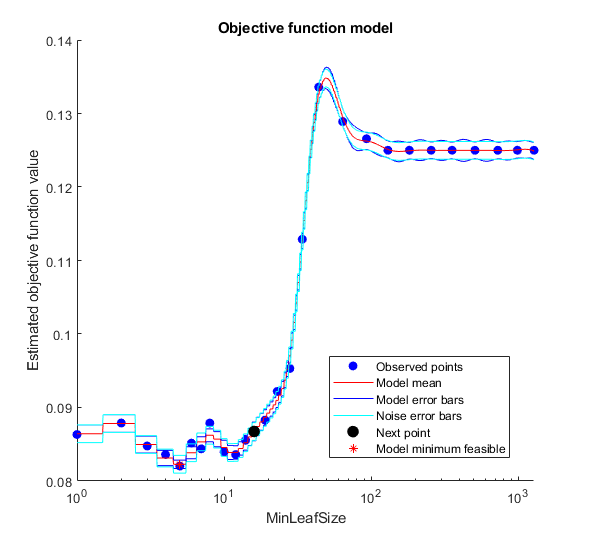


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 18.8917 seconds
Total objective function evaluation time: 1.6872

Best observed feasible point:
    MinLeafSize
    ___________

         5     

Observed objective function value = 0.082031
Estimated objective function value = 0.082273
Function evaluation time = 0.059722

Best estimated feasible point (according to models):
    MinLeafSize
    ___________

         5     

Estimated objective function value = 0.082273
Estimated function evaluation time = 0.063156



m =   ClassificationTree
                       PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
                         ResponseName: 'Var23'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 2560
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(5,:)={SE,SP,AC,FAR,DR,PPV};

m = fitctree(tdataAll,'Var23','OptimizeHyperparameters','auto')

results{6,:} = [resubLoss(m) loss(m,vdataAll)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =     56    24
    27   533


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =        92.031


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(6,:)={SE,SP,AC,FAR,DR,PPV};

m = prune(m,'Level',4)

m =   ClassificationTree
                       PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
                         ResponseName: 'Var23'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 2560
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


results{7,:} = [resubLoss(m) loss(m,vdataAll)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =     58    22
    23   537


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =        92.969


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(7,:)={SE,SP,AC,FAR,DR,PPV};

## Naive Bayes models

m = fitcnb(tdata,'Var23')

m =   ClassificationNaiveBayes
            PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
              ResponseName: 'Var23'
     CategoricalPredictors: []
                ClassNames: [0 1]
            ScoreTransform: 'none'
           NumObservations: 2560
         DistributionNames: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {2×22 cell}


  Properties, Methods


results{8,:} = [resubLoss(m) loss(m,vdata)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =     27    53
    60   500


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =        82.344


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(8,:)={SE,SP,AC,FAR,DR,PPV};


m = fitcnb(tdata,'Var23','Distribution','kernel')

m =   ClassificationNaiveBayes
            PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
              ResponseName: 'Var23'
     CategoricalPredictors: []
                ClassNames: [0 1]
            ScoreTransform: 'none'
           NumObservations: 2560
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'}
    DistributionParameters: {2×22 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'norm

results{9,:} = [resubLoss(m) loss(m,vdata)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =     44    36
    97   463


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =        79.219


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(9,:)={SE,SP,AC,FAR,DR,PPV};

m = fitcnb(tdataAll,'Var23')

m =   ClassificationNaiveBayes
            PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
              ResponseName: 'Var23'
     CategoricalPredictors: []
                ClassNames: [0 1]
            ScoreTransform: 'none'
           NumObservations: 2560
         DistributionNames: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {2×22 cell}


  Properties, Methods


results{10,:} = [resubLoss(m) loss(m,vdataAll)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =     27    53
    60   500


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =        82.344


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(10,:)={SE,SP,AC,FAR,DR,PPV};

dists = [repmat({'kernel'},1,11),repmat({'normal'},1,11)];
m = fitcnb(tdataAll,'Var23','DistributionNames',dists)

m =   ClassificationNaiveBayes
            PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
              ResponseName: 'Var23'
     CategoricalPredictors: []
                ClassNames: [0 1]
            ScoreTransform: 'none'
           NumObservations: 2560
         DistributionNames: {'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {2×22 cell}
                    Kernel: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  []  []  []  []  []  []  []  []  []  []  []}
                   Support: {'u

results{11,:} = [resubLoss(m) loss(m,vdataAll)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =     37    43
    85   475


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =     80


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(11,:)={SE,SP,AC,FAR,DR,PPV};


## Discriminant Analysis models

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        Delta |        Gamma |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |       0.125 |    0.075665 |       0.125 |       0.125 |     0.040668 |      0.24527 |
|    2 | Accept |       0.125 |    0.046591 |       0.125 |       0.125 |      0.20405 |      0.86975 |
|    3 | Accept |     0.12695 |    0.045032 |       0.125 |       0.125 |    1.047e-06 |      0.65882 |
|    4 | Accept |       0.125 |    0.045932 |       0.125 |     0.12549 |   3.2865e-06 |       0.1447 |
|    5 | Accept |       0.125 |    0.044825 |       0.125 |       0.125 |    0.0023173 |      0.20921 |
|    6 | Accept |     0.21172 |    0.049306 |       0.125 |     

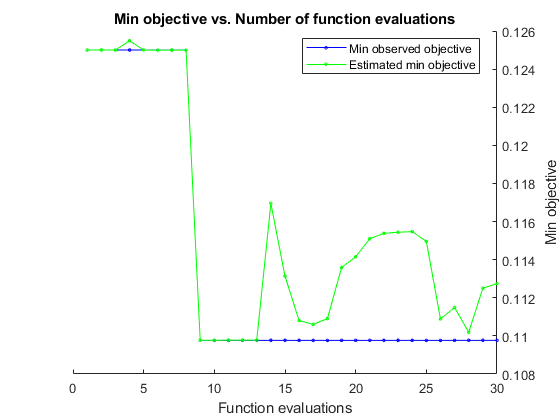

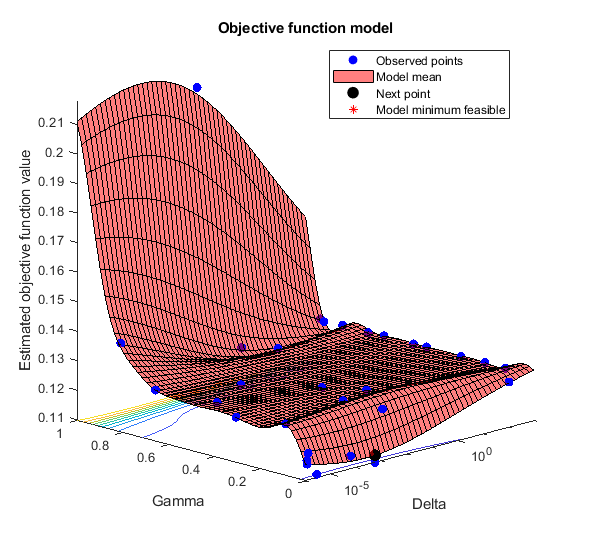


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 21.4644 seconds
Total objective function evaluation time: 1.6106

Best observed feasible point:
      Delta         Gamma   
    __________    __________

    0.00054681    8.8348e-05

Observed objective function value = 0.10977
Estimated objective function value = 0.11224
Function evaluation time = 0.046004

Best estimated feasible point (according to models):
      Delta        Gamma  
    __________    ________

    6.1568e-05    0.001681

Estimated objective function value = 0.11275
Estimated function evaluation time = 0.052338



m =   ClassificationDiscriminant
                       PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
                         ResponseName: 'Var23'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 2560
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                          DiscrimType: 'linear'
                                   Mu: [2×22 double]
                               Coeffs: [2×2 struct]


  Properties, Methods


m = fitcdiscr(tdata,'Var23','OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

results{12,:} = [resubLoss(m) loss(m,vdata)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =      7    73
     3   557


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =        88.125


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        Delta |        Gamma |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |       0.125 |    0.035897 |       0.125 |       0.125 |       38.789 |      0.17241 |
|    2 | Accept |       0.125 |    0.024598 |       0.125 |       0.125 |       2.2366 |      0.99249 |
|    3 | Accept |      0.1263 |    0.034149 |       0.125 |       0.125 |   4.3387e-05 |      0.72566 |
|    4 | Accept |       0.125 |    0.024969 |       0.125 |     0.12533 |   2.9814e-06 |      0.13314 |
|    5 | Accept |       0.125 |    0.027832 |       0.125 |       0.125 |   6.6399e-05 |      0.14757 |
|    6 | Accept |       0.125 |    0.022874 |       0.125 |     

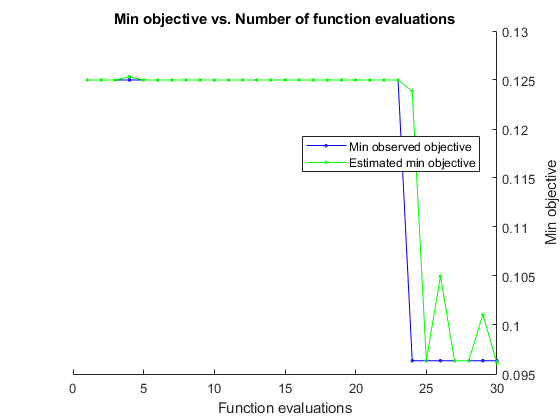

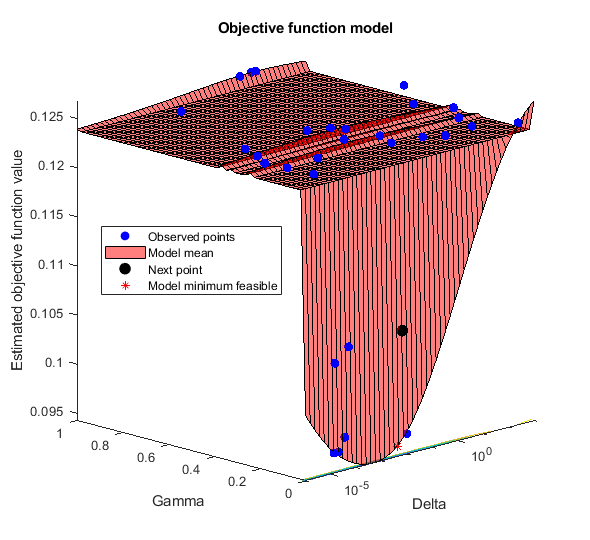


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 20.1078 seconds
Total objective function evaluation time: 0.76018

Best observed feasible point:
      Delta         Gamma   
    __________    __________

    1.9523e-05    3.1211e-05

Observed objective function value = 0.096354
Estimated objective function value = 0.096093
Function evaluation time = 0.022923

Best estimated feasible point (according to models):
      Delta         Gamma   
    __________    __________

    1.9523e-05    3.1211e-05

Estimated objective function value = 0.096093
Estimated function evaluation time = 0.025041



m =   ClassificationDiscriminant
                       PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
                         ResponseName: 'Var23'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 2560
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                          DiscrimType: 'linear'
                                   Mu: [2×22 double]
                               Coeffs: [2×2 struct]


  Properties, Methods


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(12,:)={SE,SP,AC,FAR,DR,PPV};

m = fitcdiscr(tdata,'Var23','OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('Holdout',0.3,...
    'AcquisitionFunctionName','expected-improvement-plus'))

results{13,:} = [resubLoss(m) loss(m,vdata)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =     15    65
     7   553


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =         88.75


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(13,:)={SE,SP,AC,FAR,DR,PPV};

## SVM models

m = fitcecoc(tdata,'Var23','Coding',"allpairs")                                                                                                                          

m =   ClassificationECOC
           PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
             ResponseName: 'Var23'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
           BinaryLearners: {[1×1 classreg.learning.classif.CompactClassificationSVM]}
               CodingName: 'onevsone'


  Properties, Methods


results{14,:} = [resubLoss(m) loss(m,vdata)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =      0    80
     0   560


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =          87.5


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(14,:)={SE,SP,AC,FAR,DR,PPV};

template = templateSVM('KernelFunction','gaussian');
m = fitcecoc(tdata,'Var23','Learners',template);
results{15,:} = [resubLoss(m) loss(m,vdata)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =     59    21
    14   546


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =        94.531


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(15,:)={SE,SP,AC,FAR,DR,PPV};


m = fitcecoc(tdataAll,'Var23')

m =   ClassificationECOC
           PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
             ResponseName: 'Var23'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
           BinaryLearners: {[1×1 classreg.learning.classif.CompactClassificationSVM]}
               CodingName: 'onevsone'


  Properties, Methods


results{16,:} = [resubLoss(m) loss(m,vdataAll)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =      0    80
     0   560


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =          87.5


|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |       0.125 |     0.22152 |       0.125 |       0.125 |     onevsall |       3.6288 |       468.32 |
|    2 | Accept |       0.125 |      1.2761 |       0.125 |       0.125 |     onevsall |       8.1691 |    0.0019959 |
|    3 | Accept |       0.125 |     0.19546 |       0.125 |       0.125 |     onevsall |    0.0012967 |      0.83067 |
|    4 | Accept |       0.125 |     0.50277 |       0.125 |       0.125 |     onevsone |    0.0013046 |     0.026796 |
|    5 | Best   |    0.077734 |     0.81025 |   

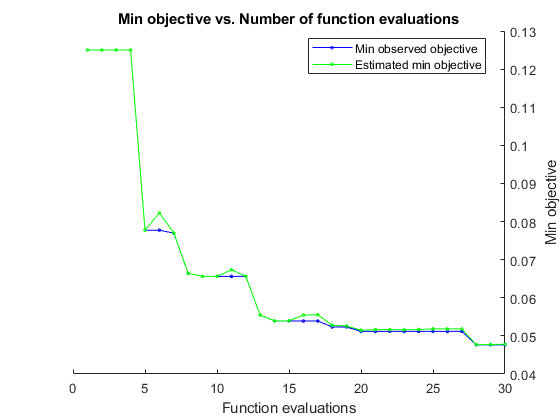


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 29.889 seconds
Total objective function evaluation time: 17.3914

Best observed feasible point:
     Coding     BoxConstraint    KernelScale
    ________    _____________    ___________

    onevsall        932.6          3.2177   

Observed objective function value = 0.047656
Estimated objective function value = 0.047805
Function evaluation time = 1.3412

Best estimated feasible point (according to models):
     Coding     BoxConstraint    KernelScale
    ________    _____________    ___________

    onevsall        932.6          3.2177   

Estimated objective function value = 0.047805
Estimated function evaluati

m =   ClassificationECOC
                       PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
                         ResponseName: 'Var23'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                       BinaryLearners: {[1×1 classreg.learning.classif.CompactClassificationSVM]}
                           CodingName: 'onevsall'
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(16,:)={SE,SP,AC,FAR,DR,PPV};

template = templateSVM('KernelFunction','gaussian');
m = fitcecoc(tdataAll,'Var23','Learners',template,'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName',...
    'expected-improvement-plus'))

results{17,:} = [resubLoss(m) loss(m,vdataAll)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,grp]=confusionmat(HDtrue,HDpred)

cm =     68    12
    17   543


grp =      0
     1


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =        95.469


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(17,:)={SE,SP,AC,FAR,DR,PPV};

## [Classification Ensembles](https://in.mathworks.com/help/stats/classification-ensembles.html)

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |     0.11641 |      0.8779 |     0.11641 |     0.11641 |  GentleBoost |           39 |      0.89744 |           59 |
|    2 | Best   |     0.10781 |      3.1109 |     0.10781 |     0.10815 |   AdaBoostM1 |           97 |    0.0051964 |            4 |
|    3 | Accept |     0.12031 |      3.6734 |     0.10781 |      0.1086 |   LogitBoost |          180 |     0.004459 |          870 |
|    4 | Accept |     0.30352 |     0.81562 |     0.10781 |   

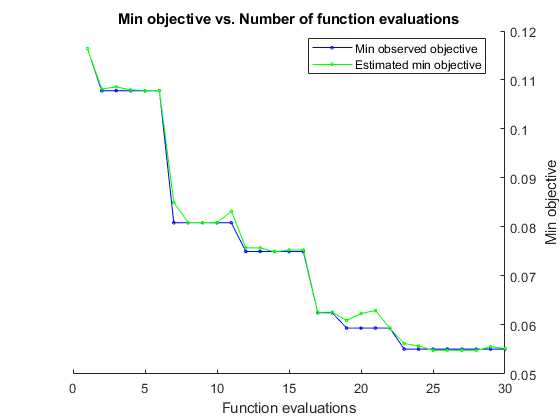


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 210.4842 seconds
Total objective function evaluation time: 190.583

Best observed feasible point:
      Method      NumLearningCycles    LearnRate    MinLeafSize
    __________    _________________    _________    ___________

    AdaBoostM1           489            0.94822         26     

Observed objective function value = 0.055078
Estimated objective function value = 0.055215
Function evaluation time = 16.2805

Best estimated feasible point (according to models):
      Method      NumLearningCycles    LearnRate    MinLeafSize
    __________    _________________    _____

m =   ClassificationEnsemble
                       PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
                         ResponseName: 'Var23'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 2560
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 489
                               Method: 'AdaBoostM1'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: [489×1 double]
                   FitInfoDescrip

t = templateTree('Reproducible',true);
m = fitcensemble(tdata,'Var23','OptimizeHyperparameters','auto','Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))

results{18,:} = [resubLoss(m) loss(m,vdataAll)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =     58    22
    13   547


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =        94.531


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(18,:)={SE,SP,AC,FAR,DR,PPV};

## Generalized Additive Model

m = fitcgam(tdata,'Var23');
results{19,:} = [resubLoss(m) loss(m,vdataAll)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred);
format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =        92.969


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(19,:)={SE,SP,AC,FAR,DR,PPV};

## Neural Networks

m = fitcnet(tdata,'Var23');
results{20,:} = [resubLoss(m) loss(m,vdataAll)];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =     62    18
    15   545


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =        94.844


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(20,:)={SE,SP,AC,FAR,DR,PPV};

## Semi-supervised graph-based method

m = fitsemigraph(tdata,'Var23',vdata);
results{21,:} = [NaN,NaN];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred);
format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =         91.25


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(21,:)={SE,SP,AC,FAR,DR,PPV};

## Automated Model Selection

Copying objective function to workers...
Done copying objective function to workers.
Learner types to explore: ensemble, knn, nb, svm, tree
Total iterations (MaxObjectiveEvaluations): 150
Total time (MaxTime): Inf

|===========================================================================================================================================|
| Iter | Active  | Eval   | Validation | Time for training | Observed min    | Estimated min   | Learner      | Hyperparameter:       Value |
|      | workers | result | loss       | & validation (sec)| validation loss | validation loss |              |                             |
|===========================================================================================================================================|
|    1 |       7 | Best   |      0.125 |           0.40625 |           0.125 |           0.125 |         tree | MinLeafSize:            324 |
|    2 |       7 | Accept |      0.125 |           0.42149 |           0.12

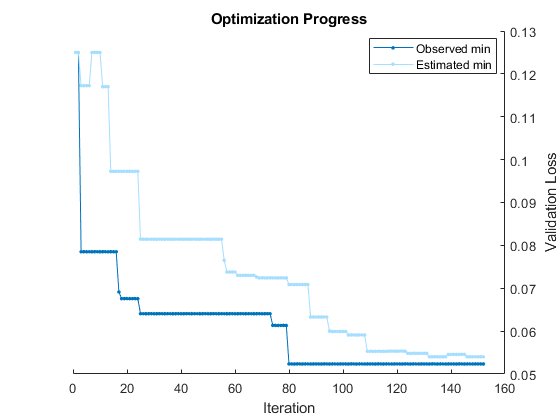


__________________________________________________________
Optimization completed.
Total iterations: 152
Total elapsed time: 173.2407 seconds
Total time for training and validation: 353.242 seconds

Best observed learner is an svm model with:
	BoxConstraint:       228.42
	KernelScale:         2.3784
Observed validation loss: 0.052344
Time for training and validation: 0.71581 seconds

Best estimated learner (returned model) is an svm model with:
	BoxConstraint:       228.42
	KernelScale:         2.3784
Estimated validation loss: 0.054013
Estimated time for training and validation: 0.7724 seconds

Documentation for fitcauto display


m =   CompactClassificationSVM
           PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
             ResponseName: 'Var23'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
                    Alpha: [321×1 double]
                     Bias: 4.2593
         KernelParameters: [1×1 struct]
           SupportVectors: [321×22 double]
      SupportVectorLabels: [321×1 double]


  Properties, Methods



options = struct('UseParallel',true);
m = fitcauto(tdata,'Var23','HyperparameterOptimizationOptions',options)

results{22,:} = [NaN, NaN];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred);
format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =        94.531


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(22,:)={SE,SP,AC,FAR,DR,PPV};

##  Linear classification model 

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |      Learner |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      0.1125 |     0.19222 |      0.1125 |      0.1125 |   1.0385e-07 |     logistic |
|    2 | Accept |       0.125 |    0.078767 |      0.1125 |     0.11333 |      0.11195 |     logistic |
|    3 | Accept |       0.125 |     0.12219 |      0.1125 |     0.11332 |   2.4449e-06 |          svm |
|    4 | Accept |       0.125 |     0.10031 |      0.1125 |     0.11324 |        2.197 |          svm |
|    5 | Accept |      0.1125 |     0.18546 |      0.1125 |      0.1125 |   9.3983e-08 |     logistic |
|    6 | Accept |     0.11289 |     0.19689 |      0.1125 |     

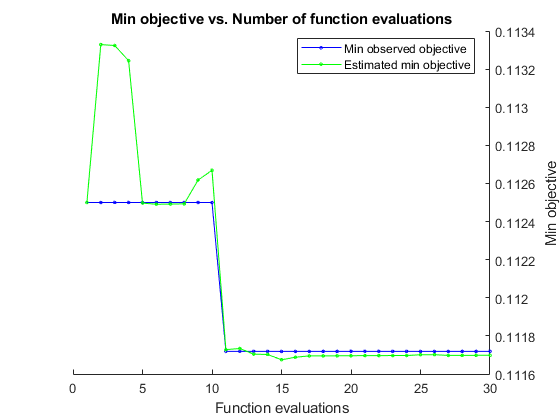

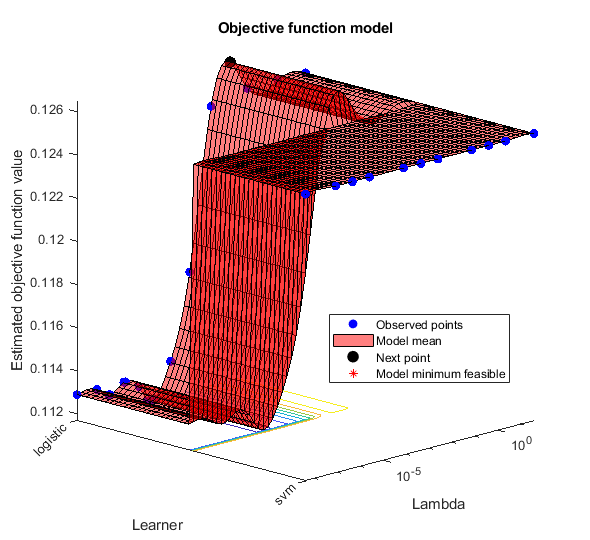


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 24.0778 seconds
Total objective function evaluation time: 4.3168

Best observed feasible point:
     Lambda      Learner 
    _________    ________

    4.699e-06    logistic

Observed objective function value = 0.11172
Estimated objective function value = 0.1118
Function evaluation time = 0.19425

Best estimated feasible point (according to models):
     Lambda      Learner 
    _________    ________

    7.231e-06    logistic

Estimated objective function value = 0.1117
Estimated function evaluation time = 0.1787



m =   ClassificationLinear
    PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
      ResponseName: 'Var23'
        ClassNames: [0 1]
    ScoreTransform: 'logit'
              Beta: [22×1 double]
              Bias: 2.3021
            Lambda: 7.231e-06
           Learner: 'logistic'


  Properties, Methods



m=fitclinear(tdata,'Var23','OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

results{23,:} = [NaN,NaN];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =     11    69
     3   557


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =         88.75


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(23,:)={SE,SP,AC,FAR,DR,PPV};

##  Kernel Classifier

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  KernelScale |       Lambda |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |       0.125 |     0.57465 |       0.125 |       0.125 |       197.49 |      0.13325 |
|    2 | Accept |     0.12734 |      1.9639 |       0.125 |     0.12617 |     0.089497 |   0.00031122 |
|    3 | Accept |     0.21797 |      1.8845 |       0.125 |     0.12867 |     0.003396 |   1.5878e-06 |
|    4 | Accept |       0.125 |     0.51567 |       0.125 |     0.12499 |    0.0018264 |     0.055981 |
|    5 | Best   |     0.10039 |      1.1601 |     0.10039 |     0.10043 |      0.80838 |    0.0024568 |
|    6 | Accept |       0.125 |      1.4089 |     0.10039 |     

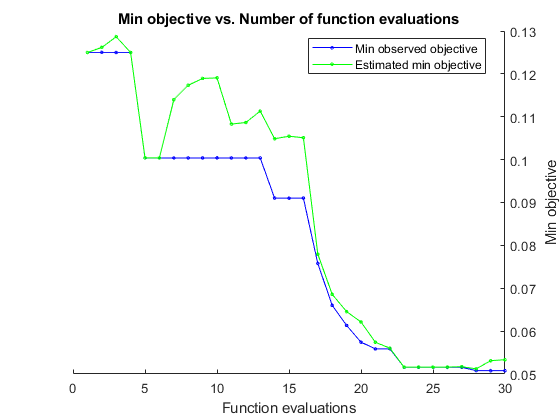

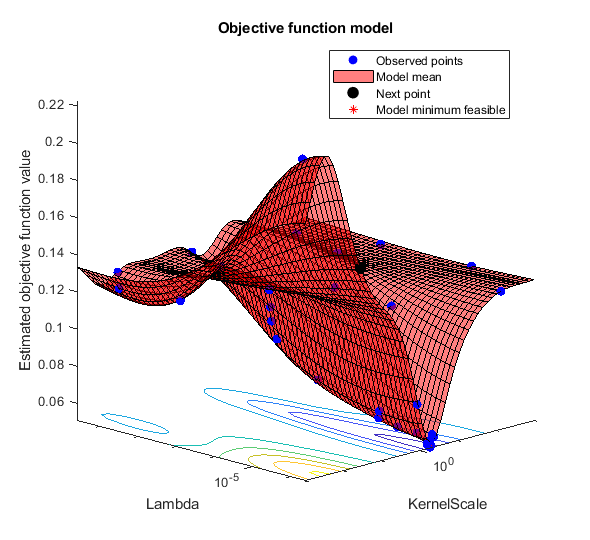


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 90.2748 seconds
Total objective function evaluation time: 71.3792

Best observed feasible point:
    KernelScale      Lambda  
    ___________    __________

      2.0239       4.2413e-07

Observed objective function value = 0.050781
Estimated objective function value = 0.053335
Function evaluation time = 4.0696

Best estimated feasible point (according to models):
    KernelScale      Lambda  
    ___________    __________

      1.9827       4.9976e-07

Estimated objective function value = 0.053339
Estimated function evaluation time = 4.3145



m =   ClassificationKernel
            PredictorNames: {'DATA1'  'DATA2'  'DATA3'  'DATA4'  'DATA5'  'DATA6'  'DATA7'  'DATA8'  'DATA9'  'DATA10'  'DATA11'  'DATA12'  'DATA13'  'DATA14'  'DATA15'  'DATA16'  'DATA17'  'DATA18'  'DATA19'  'DATA20'  'DATA21'  'DATA22'}
              ResponseName: 'Var23'
                ClassNames: [0 1]
                   Learner: 'svm'
    NumExpansionDimensions: 1024
               KernelScale: 1.9827
                    Lambda: 4.9976e-07
             BoxConstraint: 781.62


  Properties, Methods


FitInfo = struct with fields:
                  Solver: 'LBFGS-fast'
            LossFunction: 'hinge'
                  Lambda: 4.9976e-07
           BetaTolerance: 0.0001
       GradientTolerance: 1e-06
          ObjectiveValue: 0.047564
       GradientMagnitude: 0.00078125
    RelativeChangeInBeta: 7.8614e-05
                 FitTime: 1.3267
                 History: []


HyperparameterOptimizationResults =   BayesianOptimization with properties:

                      ObjectiveFcn: @createObjFcn/inMemoryObjFcn
              VariableDescriptions: [4×1 optimizableVariable]
                           Options: [1×1 struct]
                      MinObjective: 0.050781
                   XAtMinObjective: [1×2 table]
             MinEstimatedObjective: 0.053339
          XAtMinEstimatedObjective: [1×2 table]
           NumObjectiveEvaluations: 30
                  TotalElapsedTime: 90.275
                         NextPoint: [1×2 table]
                            XTrace: [30×2 table]
                    ObjectiveTrace: [30×1 double]
                  ConstraintsTrace: []
                     UserDataTrace: {30×1 cell}
      ObjectiveEvaluationTimeTrace: [30×1 double]
                IterationTimeTrace: [30×1 double]
                        ErrorTrace: [30×1 double]
                  

[m,FitInfo,HyperparameterOptimizationResults] = fitckernel(tdata,'Var23','OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))

results{24,:} = [NaN,NaN];
HDpred=predict(m,vdata);
HDtrue=vdata.Var23;
[cm,~]=confusionmat(HDtrue,HDpred)

cm =     67    13
    19   541


format short g;
SE = cm(1)/(cm(1)+cm(2));
SP = cm(4)/(cm(4)+cm(3));
AC=((cm(1)+cm(4))/(cm(1)+cm(2)+cm(3)+cm(4)))*100

AC =     95


FAR=cm(3)/(cm(3)+cm(2));
DR=cm(4)/(cm(4)+cm(1));
PPV=cm(1)/(cm(1)+cm(3));
Conf(24,:)={SE,SP,AC,FAR,DR,PPV};

## View results

disp(results)

                                     ResubLoss       Loss  
                                     __________    ________

    kNN                                0.048047    0.070313
    kNN k=5                            0.040234    0.084375
    Weighted kNN k=5                   0.052734      0.0625
    Tree                               0.044922    0.084375
    Pruned tree                         0.05625    0.076563
    Tree (all predictors)              0.032812    0.079688
    Pruned tree (all predictors)       0.041406    0.070313
    NB                                  0.17891     0.17656
    NB kernel                           0.21641     0.20781
    NB (all predictors)                 0.17891     0.17656
    NB kernel (all predictors)   


disp(sortrows(results,'Loss'))

                                     ResubLoss       Loss  
                                     __________    ________

    Gaussian SVM (all predictors)      0.021094    0.045313
    Neural Network                     0.039844    0.051563
    Gaussian SVM                       0.040625    0.054688
    Ensembles                        0.00039062    0.054688
    Weighted kNN k=5                   0.052734      0.0625
    kNN                                0.048047    0.070313
    Generalized Additive Model       0.00039062    0.070313
    Pruned tree (all predictors)       0.041406    0.070313
    Pruned tree                         0.05625    0.076563
    Tree (all predictors)              0.032812    0.079688
    kNN k=5                      


disp(Conf)

                                     Sensitivity    Specificity    Detection accuracy    False alarm rate    Detection rate     Positive predictive value (PPV) or Precision
                                     ___________    ___________    __________________    ________________    _______________    ____________________________________________

    kNN                                0.69231        0.96903            92.969              0.37778             0.89412                           0.7875                   
    kNN k=5                            0.62037        0.97556            91.562              0.24074             0.88567                           0.8375                   
    Weighted kNN k=5                   0.71739      


disp(sortrows(Conf,'Detection accuracy'))

                                     Sensitivity    Specificity    Detection accuracy    False alarm rate    Detection rate     Positive predictive value (PPV) or Precision
                                     ___________    ___________    __________________    ________________    _______________    ____________________________________________

    NB kernel                          0.31206        0.92786            79.219              0.27068             0.91321                             0.55                   
    NB kernel (all predictors)         0.30328        0.91699                80              0.33594             0.92773                           0.4625                   
    NB                                 0.31034      

Conf

Conf = 24×6 table
                                    Sensitivity    Specificity    Detection accuracy    False alarm rate    Detection rate     Positive predictive value (PPV) or Precision
                                    ___________    ___________    __________________    ________________    _______________    ____________________________________________

    kNN                               0.69231        0.96903            92.969              0.37778             0.89412                           0.7875                   
    kNN k=5                           0.62037        0.97556            91.562              0.24074             0.88567                           0.8375                   
    Weighted kNN k=5                  